clear all;
close all;

## 環境の宣言

T1 = 1;
K1 = 1;
F = 1;
[A, B, C, D] = tf2ss([K1], [T1 1]);
sys = ss(A,B,C,D);
sysd1 = c2d(sys, 0.01);

T2 = 1.5;
K2 = 0.75;
[A, B, C, D] = tf2ss([K2], [T2 1]);
sys = ss(A,B,C,D);
sysd2 = c2d(sys, 0.01);

C1 = [C -1];

x0 = [0; 1];

### 報酬関数の設計

Q = 1000;
R = 1;

Q1 = C1'*Q*C1;

## 環境の遷移列の作成

contextSequence = [1*ones(500, 1); 2*ones(500, 1); 1*ones(500, 1)];
% contextSequence = 1 * ones(1500, 1);

### 環境のインスタンス

subEnv1 = rlDiscreteLQTEnv(sysd1.A, sysd1.B, sysd1.C, F, Q, R,'x0', x0);
subEnv2 = rlDiscreteLQTEnv(sysd2.A, sysd2.B, sysd2.C, F, Q, R);

env = rlMultipleEnvironment({subEnv1, subEnv2}, contextSequence);

## エージェントの作成

### LQT Agentのインスタンス

#### エージェントオプションの作成

moduleAgentOpts = rlLQTAgentOptions('StepNumPerIteration', 20, 'DiscountFactor', 0.8, 'StopExplorationValue', 0, 'SaveExperiences', true);
moduleAgentOpts.NoiseOptions.Mean = 0;
moduleAgentOpts.NoiseOptions.Variance = 2;

#### エージェントのインスタンス

LQTAgent = rlLQTAgent(getObservationInfo(env), getActionInfo(env), moduleAgentOpts);

### AMLQT Agentのインスタンス

#### エージェントオプションの作成

agentOpts = rlAdaptiveModularAgentOptions("Vigilance", -1e-3, "LearningPeriod", 20, "SaveExperiences", true);

#### エージェントのインスタンス

createModuleFcn = @(moudleAgents, evaluateValues) createLQTAgentModule(getObservationInfo(env), getActionInfo(env), moduleAgentOpts, moudleAgents, evaluateValues);
AMLQTAgent = rlAdaptiveModularAgent(createModuleFcn, agentOpts);

## エージェントの学習

trainingOpts = rlTrainingOptions(...
    'MaxEpisodes',1, ...
    'MaxStepsPerEpisode',1500, ...
    'StopTrainingValue', 100000, ...
    'Verbose',true, ...
    'Plots','none');

rng(0)
AMLQTTrainingStats = train(AMLQTAgent, env, trainingOpts);

Episode:   1/  1 | Episode Reward : -38460.92 | Episode Steps: 1500 | Avg Reward : -38460.93 | Step Count : 1500


rng(0)
LQTTrainingStats = train(LQTAgent, env, trainingOpts);

Episode:   1/  1 | Episode Reward : -55825.79 | Episode Steps: 1500 | Avg Reward : -55825.79 | Step Count : 1500


save("results.mat", "AMLQTAgent", "AMLQTTrainingStats", "LQTAgent", "LQTTrainingStats");

## 実験結果のプロット

AMLQTExperience = getExperiences(AMLQTAgent);
LQTExperience = getExperiences(LQTAgent);

AMLQTObservation     = cellfun(@(x)x{1}, AMLQTExperience, 'UniformOutput', false);
AMLQTAction          = cellfun(@(x)x{2}, AMLQTExperience, 'UniformOutput', false);
AMLQTReward          = cellfun(@(x)x{3}, AMLQTExperience, 'UniformOutput', false);

LQTObservation     = cellfun(@(x)x{1}, LQTExperience, 'UniformOutput', false);
LQTAction          = cellfun(@(x)x{2}, LQTExperience, 'UniformOutput', false);
LQTReward          = cellfun(@(x)x{3}, LQTExperience, 'UniformOutput', false);

selectedModuleID = getBuffer(AMLQTAgent.SelectedModuleID);
evaluateValues = getBuffer(AMLQTAgent.EvaluateValues);

t = 0 : 0.01 : 14.99;

### 報酬のプロット

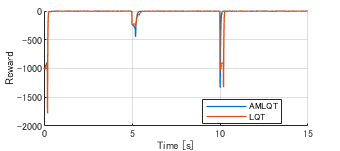

figure;
hold on;
plot(t, cell2mat(AMLQTReward), t, cell2mat(LQTReward), "LineWidth", 1);
grid on;
xlabel('Time [s]', "FontSize", 8)
ylabel("Reward", "FontSize", 8)
legend("AMLQT", "LQT", "Location", "best");
set(gcf, 'WindowStyle', 'normal');              %ウィンドウ領域(Positon)を設定できるように変更
%出力するサイズをA4用紙サイズに変更
set(gcf, 'Units', 'centimeters');
set(gcf, 'Position', [0, 0, 9, 4]);
savefig("reward.fig");
saveas(gcf, "reward.eps", "epsc")

### 各モジュールの評価値をプロット

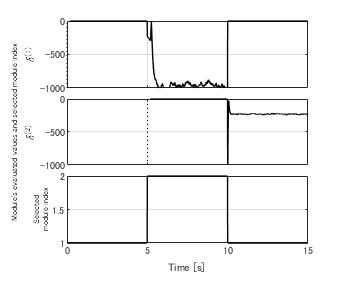

figure;
tl =tiledlayout(length(AMLQTAgent.ModuleAgents) + 1, 1, "TileSpacing", "none");
for i = 1 : length(AMLQTAgent.ModuleAgents)
    ax(i) = nexttile;
    module{i} =  cellfun(@(x) extractEvaluateValues(x, i), evaluateValues);
    plot(t, module{i}, "k", "LineWidth", 1);
    ylim([-1000 0]);
    ylabel("$\delta^{("+i+")}$", "Interpreter", "latex");
    % モジュールが生成されたタイミングをプロット
    createModuleTime = t(min(find(~isnan(module{i}))));
    y = get(ax(i), "ylim");
    line([createModuleTime createModuleTime], y, "Color", "k", "LineStyle", ":", "LineWidth", 0.5);
    ylim(y);  % モジュール生成時間の追加によるylimの変動を修正
    grid on;
end
ax(i+1) = nexttile;
plot(t, cell2mat(selectedModuleID), "k", "LineWidth", 1);
grid on;
ylabel({"Selected", "module index"}, "FontSize", 6);

linkaxes(ax, "x");
for i = 1 : length(ax) - 1
    xticklabels(ax(i),{})
end
xlabel(tl,'Time [s]', "FontSize", 8)
ylabel(tl,"Module's evaluated values and selected module index", "FontSize", 6)

set(gcf, 'WindowStyle', 'normal');              %ウィンドウ領域(Positon)を設定できるように変更
%出力するサイズをA4用紙サイズに変更
set(gcf, 'Units', 'centimeters');
set(gcf, 'Position', [0, 0, 9, 7.5]);
savefig("evaluatedValues.fig");
saveas(gcf, "evaluatedValues.eps")

### 最適制御則との比較

#### 環境１の最適制御則

gamma = LQTAgent.AgentOptions.DiscountFactor;
T = blkdiag(sysd1.A, F);
B1 = [sysd1.B; 0];
C1 = [sysd1.C -1];
Q1 = C1'*Q*C1;

A = sqrt(gamma)*T;
B = sqrt(gamma)*B1;
[~, Koptimal1, ~] = idare(A, B, Q1, R, [], []);

#### 環境2の最適制御則

gamma = LQTAgent.AgentOptions.DiscountFactor;
T = blkdiag(sysd2.A, F);
B1 = [sysd2.B; 0];
C1 = [sysd2.C -1];
Q1 = C1'*Q*C1;

A = sqrt(gamma)*T;
B = sqrt(gamma)*B1;
[~, Koptimal2, ~] = idare(A, B, Q1, R, [], []);

#### 比較

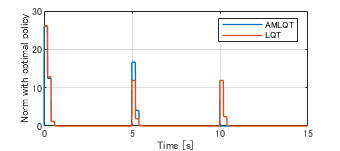

K = LQTAgent.KBuffer;
for i = 1 : LQTAgent.KUpdate-1
    if contextSequence(1+20*(i-1)) == 1
        err(1+20*(i-1):20+20*(i-1)) = norm(Koptimal1 - K{i});
    else
        err(1+20*(i-1):20+20*(i-1)) = norm(Koptimal2 - K{i});
    end
end

K{1} = AMLQTAgent.ModuleAgents{1}.KBuffer;
K{2} = AMLQTAgent.ModuleAgents{2}.KBuffer;
count = [0 0];
for i = 2 : 1499
    if contextSequence(i+1) == 1
        AMLQTErr(i) = norm(Koptimal1 - K{selectedModuleID{i}}{floor(count(1)/20) + 1});
    else
        AMLQTErr(i) = norm(Koptimal2 - K{selectedModuleID{i}}{floor(count(2)/20) + 1});
    end
    count(selectedModuleID{i}) = count(selectedModuleID{i}) + 1;
end
AMLQTErr(1500) = nan;

figure
plot(t, AMLQTErr, t, err, "Linewidth", 1);
grid on;
xlabel('Time [s]', "FontSize", 8)
ylabel("Norm with optimal policy", "FontSize", 8)
legend("AMLQT", "LQT");
set(gcf, 'WindowStyle', 'normal');              %ウィンドウ領域(Positon)を設定できるように変更
%出力するサイズをA4用紙サイズに変更
set(gcf, 'Units', 'centimeters');
set(gcf, 'Position', [0, 0, 9, 4]);
savefig("norm.fig");
saveas(gcf, "norm.eps", "epsc")

function ret = extractEvaluateValues(val, moduleID)
    if length(val) < moduleID
        ret = nan;
    else
        ret = val(moduleID);
    end
end